## Задание 1. Исследование LQR.

Начальные условия на задание:

A = [12, -1, 14; 
     6, 0, 6;
     -6, -2, -8]

A =     12    -1    14
     6     0     6
    -6    -2    -8


B = [11;
      7;
      -7]

B =     11
     7
    -7


**Сделать вывод об управляемости и стабилизируемости системы.**

U = ctrb(A, B)

U =     11    27   -36
     7    24    18
    -7   -24   -18


U = [B , A*B , A^2 * B]

U =     11    27   -36
     7    24    18
    -7   -24   -18


rank(U)

ans = 2

Проверка критерия Хаутуса:

EIG_A = eig(A)

EIG_A =    3.0000 + 3.0000i
   3.0000 - 3.0000i
  -2.0000 + 0.0000i


l1 = 3 + 3j; l2 = 3 - 3j; l3 = -2;

vpa([A - eye(3).*l1 , B])

$$ans = \left(\begin{array}{cccc} 9.0-3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0-3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0-3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l2 , B])

$$ans = \left(\begin{array}{cccc} 9.0+3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0+3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0+3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l3 , B])

$$ans = \left(\begin{array}{cccc} 14.0 & -1.0 & 14.0 & 11.0\\ 6.0 & 2.0 & 6.0 & 7.0\\ -6.0 & -2.0 & -6.0 & -7.0 \end{array}\right)$$


rank([A - eye(3).*l1 , B])

ans = 3

rank([A - eye(3).*l2 , B])

ans = 3

rank([A - eye(3).*l3 , B])

ans = 2

**A --> Стабилизируема, но не управляема**

*Максимально возможная степень устойчивость, которую можем добиться: -2*

C = [1 1 1];
x0 = [1 1 1]';
simTimeStart = 0;
simTimeEnd = 8;
step = 0.001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

Не управляемые собственные числа нам не достичь, поэтому они должны в наборе остаться...

В моём случае lambda = -2 неуправляемо, значит оно должно быть в наборе...

Выберем значения матриц Q, R и для них ещё коэфициент альфа подберём

a = 20;
Q = diag([3, 3, 3]); % "Cкорость" - чем больше диагональные элементы, тем больше скорость
R = 2; % Штраф за управление - чем больше, тем меньшее управления мы позволяем
% Скорость (качество переходного процесса) VS затраты (управление)

Начальные условия для решений уравнения Риккати:

Так как у нас система стабилизируема, то лучше применить **усечение системы,**

иначе численные методы вообще не работают и чемодан вокзал россия...

Начальные условия этого пункта задания

nu = 1;

## **1- Набор (Q, R)**

Q = diag([3 3 3]);

P = are(A, 1*B*R^-1 *B', Q)

P =    48.6140  -37.2233   42.1481
  -37.2233   29.4014  -31.9877
   42.1481  -31.9877   37.1383


K = -inv(R) * B' * P

K =    10.4230  -10.1340   10.1263



J_min = x0' * P * x0

J_min = 61.0279

EIG_K3 =  eig(A + B * K) 

EIG_K3 =   -17.8107
   -3.3582
   -2.0000


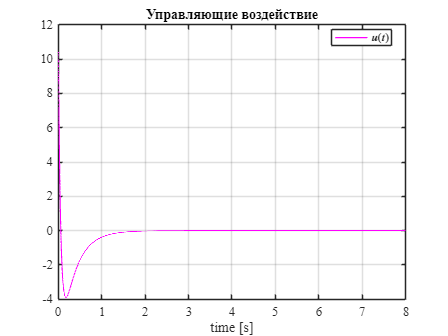

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Q = diag([3, 3, 3]);
R = 2;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x_plant = out.x_plant.Data;
% u = out.u.Data';
u1 = K * out.x_plant.Data';
J_exp1 = out.J_exp.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u1, 'magenta', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("lqr1_u1");

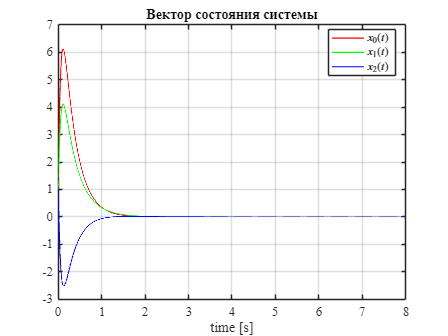


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); grid on;
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("lqr1_x1");

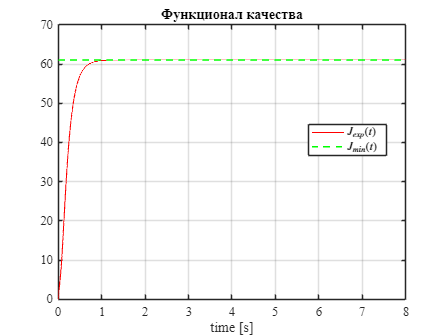



h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, J_exp1, 'r', 'LineWidth', 1.0); hold on
plot(time, ones(size(time)) * J_min, 'g--', 'LineWidth', 1.5); grid on;
xlabel('time [s]');                                   
legend('$J_{exp}(t)$', '$J_{min}(t)$',...
        'Location', 'best', 'Interpreter', 'latex');
title('Функционал качества');
save_file("funcJ1_1");

## **2- Набор (aQ, R)**

Q = a * diag([3, 3, 3]);
R = 2;

P = are(A, 1*B*R^-1 *B', Q)

P =   764.4185 -574.5082  639.2419
 -574.5082  440.4123 -473.6414
  639.2419 -473.6414  542.9821


K = -inv(R) * B' * P

K =    43.8238  -39.3928   42.3519



J_min = x0' * P * x0

J_min = 929.9974

EIG_K3 =  eig(A + B * K) 

EIG_K3 =   -80.9940
   -3.1573
   -2.0000


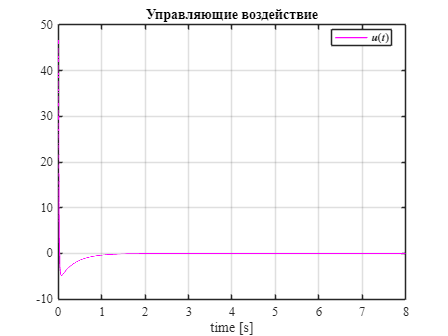

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x_plant = out.x_plant.Data;
% u = out.u.Data';
u2 = K * out.x_plant.Data';
J_exp2 = out.J_exp.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u2, 'magenta', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("lqr1_u2");

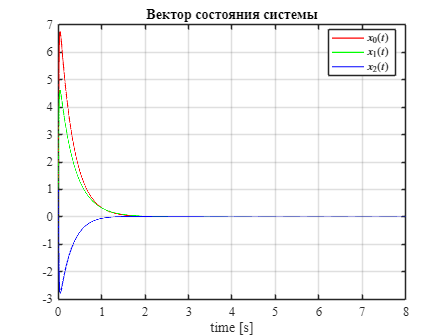


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); grid on;
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("lqr1_x2");

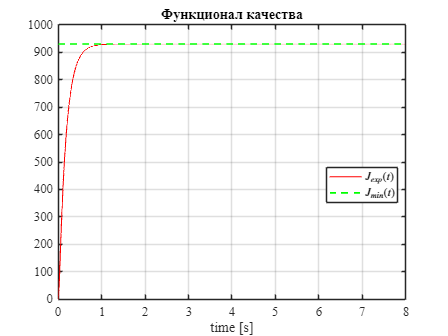



h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, J_exp2, 'r', 'LineWidth', 1.0); hold on
plot(time, ones(size(time)) * J_min, 'g--', 'LineWidth', 1.5); grid on;
xlabel('time [s]');                                   
legend('$J_{exp}(t)$', '$J_{min}(t)$',...
        'Location', 'best', 'Interpreter', 'latex');
title('Функционал качества');
save_file("funcJ1_2");

## **3 - Набор (Q, aR)**

Q = diag([3, 3, 3]);
R = a * 2;

P = are(A, 1*B*R^-1 *B', Q)

P =   154.2706 -116.0053  147.4856
 -116.0053   95.3714 -110.4262
  147.4856 -110.4262  142.1863


K = -inv(R) * B' * P

K =     3.6865   -4.1131    3.6486



J_min = x0' * P * x0

J_min = 233.9366

EIG_K3 =  eig(A + B * K) 

EIG_K3 =   -3.8906 + 2.6314i
  -3.8906 - 2.6314i
  -2.0000 + 0.0000i


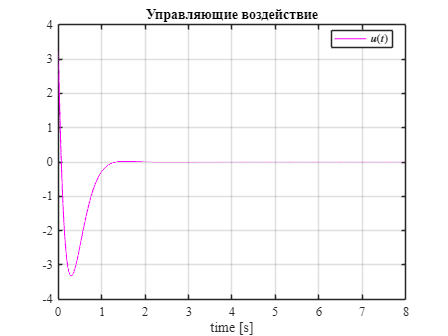

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x_plant = out.x_plant.Data;
% u = out.u.Data';
u3 = K * out.x_plant.Data';
J_exp3 = out.J_exp.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u3, 'magenta', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("lqr1_u3");

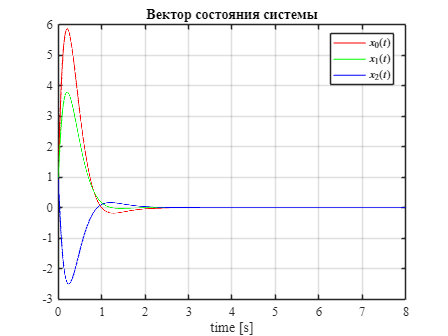


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); grid on;
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("lqr1_x3");

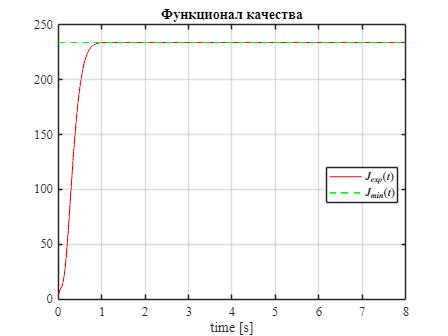



h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, J_exp3, 'r', 'LineWidth', 1.0); hold on
plot(time, ones(size(time)) * J_min, 'g--', 'LineWidth', 1.5); grid on;
xlabel('time [s]');                                   
legend('$J_{exp}(t)$', '$J_{min}(t)$',...
        'Location', 'best', 'Interpreter', 'latex');
title('Функционал качества');
save_file("funcJ1_3");

## **4- Набор (aQ, aR)**

Q = a * diag([3, 3, 3]);
R = a * 2;

P = are(A, 1*B*R^-1 *B', Q)

P =   972.2797 -744.4654  842.9628
 -744.4654  588.0280 -639.7549
  842.9628 -639.7549  742.7654


K = -inv(R) * B' * P

K =    10.4230  -10.1340   10.1263



J_min = x0' * P * x0

J_min = 1.2206e+03

EIG_K3 =  eig(A + B * K) 

EIG_K3 =    -3.3582
  -17.8107
   -2.0000


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x_plant = out.x_plant.Data;
% u = out.u.Data';
u4 = K * out.x_plant.Data';
J_exp4 = out.J_exp.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u4, 'magenta', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("lqr1_u4");

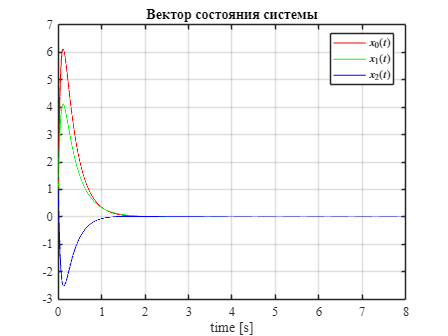


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); grid on;
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("lqr1_x4");

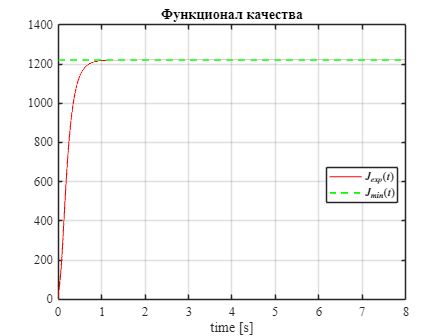



h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, J_exp4, 'r', 'LineWidth', 1.0); hold on
plot(time, ones(size(time)) * J_min, 'g--', 'LineWidth', 1.5); grid on;
xlabel('time [s]');                                   
legend('$J_{exp}(t)$', '$J_{min}(t)$',...
        'Location', 'best', 'Interpreter', 'latex');
title('Функционал качества');
save_file("funcJ1_4");

## **Общее сравнение**

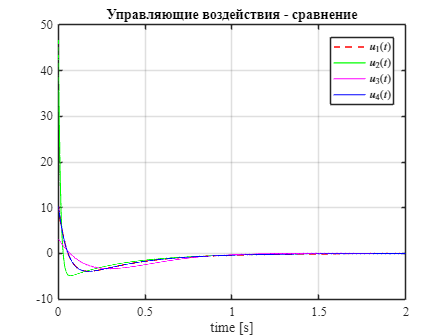

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u1, 'r--', 'LineWidth', 1.5); hold on; grid on;
plot(time, u2, 'g', 'LineWidth', 1.0); 
plot(time, u3, 'magenta', 'LineWidth', 1.0); 
plot(time, u4, 'b', 'LineWidth', 1.0); 
xlabel('time [s]');                                   
legend('$u_1(t)$', '$u_2(t)$', '$u_3(t)$', '$u_4(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействия - сравнение')
xlim([0 2])
save_file("lqr1_u_all");

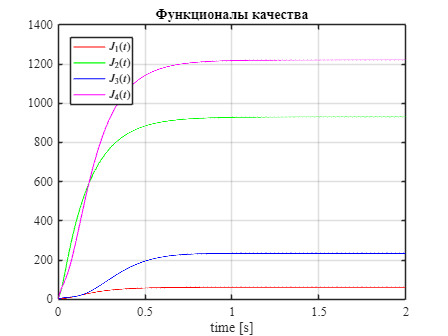



h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, J_exp1, 'r', 'LineWidth', 1.0); hold on; grid on;
plot(time, J_exp2, 'g', 'LineWidth', 1.0);
plot(time, J_exp3, 'b', 'LineWidth', 1.0);
plot(time, J_exp4, 'magenta', 'LineWidth', 1.0);

xlabel('time [s]');                                   
legend('$J_{1}(t)$', '$J_{2}(t)$', '$J_{3}(t)$', '$J_{4}(t)$',...
        'Location', 'best', 'Interpreter', 'latex');
title('Функционалы качества');
xlim([0 2])
save_file("funcJ1_all");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab10\latex10\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end